clear all
fs = 500;
t_sample = 1/fs;
t = 0:t_sample:7;
omega = 19;
A = 1;
v = A*sin(omega*t);
f = omega/(2*pi)

f = 3.0239

T = 1/f

T = 0.3307

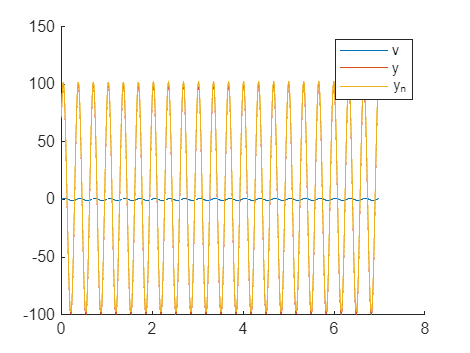

phase = pi/4;

B = 100;
y =  B*sin( (omega*t) + phase);

y_ramp = y + 2.0 + t*0.1;
figure
hold on
plot(t,v)
plot(t,y)
plot(t,y_ramp)
hold off
legend(["v","y","y_n"])


% xlim([0 1.2])


max_samples_per_period = ceil(T/t_sample)*1;
angular_resolution = 360/max_samples_per_period

angular_resolution = 2.1687

maxlag_n = ceil(max_samples_per_period/4) % just +-90° per side

maxlag_n = 42

gain= B/A

gain = 100

## debias


t_start = 1;
t_end = 7;
Focus_Period = t_end - t_start;

idx_start = t_start/t_sample +1;
idx_end = t_end/t_sample +1;
y_ramp_focus = y_ramp(idx_start:idx_end);
t_focus = t(idx_start:idx_end);
Integ = trapz(t_focus,y_ramp_focus)

Integ = 18.9135

b = Integ/Focus_Period

b = 3.1522


v_focus = v(idx_start:idx_end);
y_focus = y(idx_start:idx_end);
y_deb = y_ramp_focus - b;
quant_error = trapz(t_focus,y_deb)

quant_error = 9.4091e-15

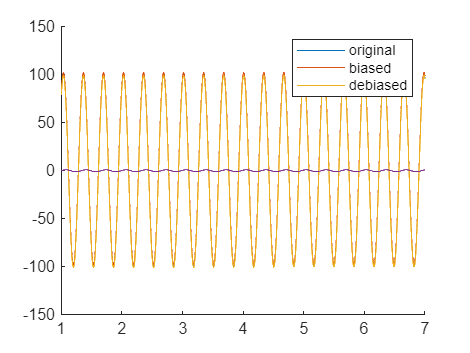

figure
hold on
plot(t_focus,y_focus)
plot(t_focus,y_ramp_focus)
plot(t_focus,y_deb)
plot(t_focus,v_focus)
legend(["original","biased","debiased"])
hold off



[c,lags] = xcorr(v_focus,y_focus,maxlag_n,'biased' );
% c_ramp = xcorr(v,y_ramp,maxlag_n,'biased' );
c_ramp = xcorr(v_focus,y_deb,maxlag_n,'biased' );

norm_factor = 2;% 1/size(t,2)/2;
c = c*norm_factor;
c_ramp = c_ramp*norm_factor;

[c_max, cmaxid] = max(c);
[c_ramp_max, cmax_ramp_id] = max(c_ramp);


maxlag_time = (2*maxlag_n + 1) * t_sample;
lags_time = lags * t_sample;
lags_angle = lags_time * 360 / T;

angle_delay_pure = lags_angle(cmaxid)

angle_delay_pure = 43.5448

angle_delay_ramp  = lags_angle(cmax_ramp_id)

angle_delay_ramp = 43.5448

A

A = 1

B

B = 100

c_max

c_max = 99.3655

c_ramp_max

c_ramp_max = 99.3578

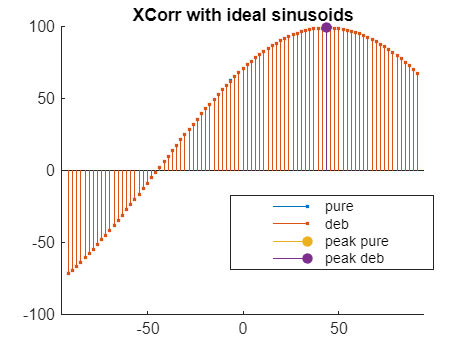


figure
hold on
stem(lags_angle,c,".")
stem(lags_angle,c_ramp,".")
stem(angle_delay_pure,c_max,"filled")
stem(angle_delay_ramp,c_ramp_max,"filled")
title("XCorr with ideal sinusoids")
legend(["pure", "deb","peak pure","peak deb"], "Position", [0.5543 0.2845 0.3035, 0.1142])
hold off;